EPxROI = info.analysis{1,1}.indFly{1,flyfly}.p6_averagedTrials.snipMat;
ROIxEP = transpose(EPxROI)

ROIxEP = 8×12 cell array
    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}
    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}
    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}
    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}
    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double}    {189×1 double


dataMatrix = cell2mat(ROIxEP)

dataMatrix =     0.0653   -0.1268    0.0139   -0.2330    0.5058    0.0318    0.2477   -0.0790   -0.1199   -0.0186   -0.0645   -0.0267
   -0.0985    0.0041    0.2116   -0.0712    0.0208    0.0233   -0.0208   -0.1104   -0.3500    0.0355   -0.0012    0.0609
   -0.1846   -0.1209    0.2078    0.0350    0.0531   -0.0396    0.0675   -0.1429   -0.0336    0.1024    0.2967    0.0595
   -0.4222    0.0378   -0.0608    0.0075    0.2096    0.1102    0.0718   -0.2341   -0.1892    0.1245   -0.1309    0.1158
   -0.1635    0.1501    0.0202   -0.2877    0.0535   -0.1178    0.0272   -0.2479   -0.1635   -0.0875    0.0563    0.1323
   -0.0801    0.3086   -0.1885   -0.2409   -0.0207   -0.1103    0.1724   -0.2441   -0.2398   -0.1647   -0.1004   -0.0951
    0.0408    0.0419   -0.0744   -0.1531   -0.1174   -0.0147   -0.0942   -0.2337   -0.0791   -0.1497   -0.0839    0.0593
    0.0685    0.0715   -0.1266   -0.1937   -0.0192    0.0161   -0.2263   -0.0737   -0.2822   -0.0789    0.0124   -0.1275
    0.1799   -0.200

normalizedData = zscore(dataMatrix)

normalizedData =    -0.2853   -0.5923   -0.3414   -1.0528    1.3874   -0.1208    0.2269   -0.4479   -0.5739   -0.3212   -0.6396   -0.3138
   -0.6232   -0.2761    0.1811   -0.5668   -0.2207   -0.1500   -0.2986   -0.5177   -1.1112   -0.1879   -0.5019   -0.0408
   -0.8009   -0.5781    0.1712   -0.2477   -0.1136   -0.3662   -0.1258   -0.5902   -0.3725   -0.0230    0.1469   -0.0452
   -1.2912   -0.1947   -0.5388   -0.3303    0.4051    0.1485   -0.1173   -0.7933   -0.7357    0.0316   -0.7842    0.1302
   -0.7574    0.0767   -0.3246   -1.2172   -0.1124   -0.6347   -0.2047   -0.8241   -0.6758   -0.4912   -0.3767    0.1819
   -0.5853    0.4598   -0.8762   -1.0766   -0.3584   -0.6092    0.0795   -0.8157   -0.8538   -0.6817   -0.7180   -0.5269
   -0.3360   -0.1848   -0.5748   -0.8126   -0.6788   -0.2806   -0.4421   -0.7926   -0.4786   -0.6448   -0.6819   -0.0458
   -0.2788   -0.1132   -0.7126   -0.9347   -0.3534   -0.1749   -0.7005   -0.4361   -0.9529   -0.4702   -0.4722   -0.6277
   -0.0489   -0

[coeff, score, latent, ~, explained] = pca(normalizedData)

coeff =    -0.4218    0.2758   -0.0715    0.1482   -0.1642    0.4565    0.0848   -0.3336   -0.0580   -0.0234    0.4441    0.4050
   -0.1834   -0.3998   -0.3873   -0.1729   -0.0300    0.1102    0.3154    0.0280   -0.4529   -0.3743   -0.3570    0.2018
    0.3004   -0.1322   -0.2175    0.6298    0.0564    0.2112    0.1892    0.3299    0.4112   -0.1530   -0.0429    0.2481
    0.4361    0.2130   -0.2496   -0.1869    0.2284    0.2344   -0.1330    0.2337   -0.3186   -0.3295    0.4826   -0.2117
   -0.0539    0.4682   -0.1733    0.1535   -0.0344   -0.3127    0.4691    0.3523   -0.3440    0.4015    0.0030    0.0393
   -0.0515    0.2640   -0.1076    0.1168    0.8262    0.0547   -0.0261   -0.3444   -0.0104    0.0299   -0.3082    0.0382
    0.1569    0.1668    0.4883    0.1101   -0.1327    0.4506    0.4436   -0.1215   -0.1215   -0.1388   -0.2500   -0.4101
   -0.4337   -0.0584   -0.2069   -0.2338    0.1317    0.4713   -0.0419    0.4440    0.2559    0.3002   -0.0707   -0.3348
    0.2550   -0.4065   -

score =    -0.6300    0.6065    0.9402    0.7581   -0.2500   -1.2239    0.4122    0.3715   -0.3952    0.6692   -0.2939   -0.0827
   -0.2104   -0.0499    0.6588    0.5114   -0.1110   -0.9011   -0.6537    0.4149    0.2355   -0.5532   -0.4642    0.1652
    0.6115   -0.0484    0.5767    0.1345   -0.2614   -0.7418   -0.3813    0.2711    0.3506   -0.0436   -0.2169    0.0637
    0.0602    0.2069    0.4873    0.2715    0.0792   -1.5641   -0.4324    0.1780   -0.4368   -0.2935   -0.6934   -0.5667
   -0.4109   -0.4696    0.8563    0.0792   -0.6462   -1.4257   -0.0749    0.0395    0.1866   -0.4150   -0.5898    0.1867
   -0.7821   -0.8311    1.3422   -0.0288   -0.4668   -1.1424   -0.2343   -0.0415   -0.6032   -0.5795   -0.4965    0.0917
   -0.5711   -0.5906    0.8867    0.0580   -0.1556   -1.1630   -0.5496   -0.3987    0.1499   -0.5263    0.0369    0.0982
   -0.8740   -0.4637    0.9689   -0.0034   -0.0183   -1.0245   -0.8718    0.0752   -0.2030   -0.1030   -0.2088    0.4752
   -0.5256   -0.1092    

latent =     2.1879
    2.0623
    1.7036
    1.1164
    1.0412
    0.9541
    0.7966
    0.5519
    0.4611
    0.4379


explained =    18.2328
   17.1861
   14.1968
    9.3037
    8.6770
    7.9508
    6.6386
    4.5991
    3.8427
    3.6492


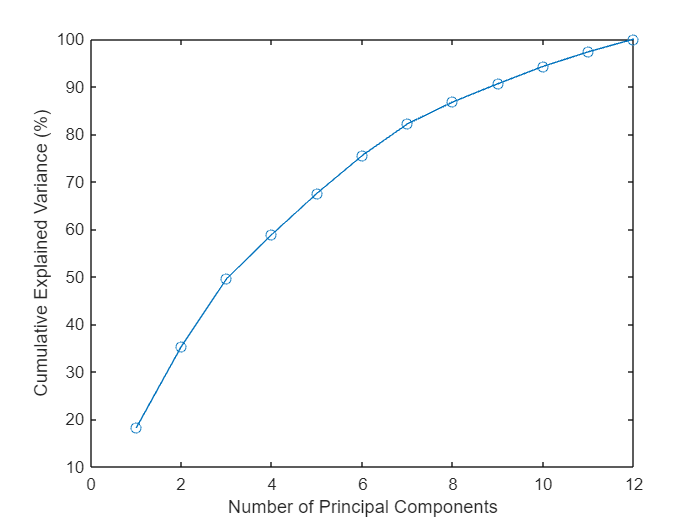

%%
cumulativeExplained = cumsum(explained);
plot(cumulativeExplained, '-o');
xlabel('Number of Principal Components');
ylabel('Cumulative Explained Variance (%)');



%%
numComponentsToKeep = 3; % Adjust based on your analysis
dataInPCSpace = normalizedData * coeff(:, 1:numComponentsToKeep);